## Problem 3: Practical PID Implementation Challenges

#### a) Observing Integral Windup (Without Anti-Windup):

• Design a PI controller with Kp = 5, Ki = 8 

• Apply a large step input (setpoint = 5) to intentionally cause saturation 3 

• Implement actuator saturation using max(min(u, 10),-10) 

• Important: In your for-loop, calculate the unsaturated control signal u and the saturated signal usat, but continue integrating the error normally (without considering saturation) 

• Plot: reference, output, control signal (both saturated and unsaturated), and integral term over time 

• Observe and describe:– When does saturation occur?– What happens to the integral term during saturation?– How does this affect overshoot and settling time when the output finally approaches setpoint?

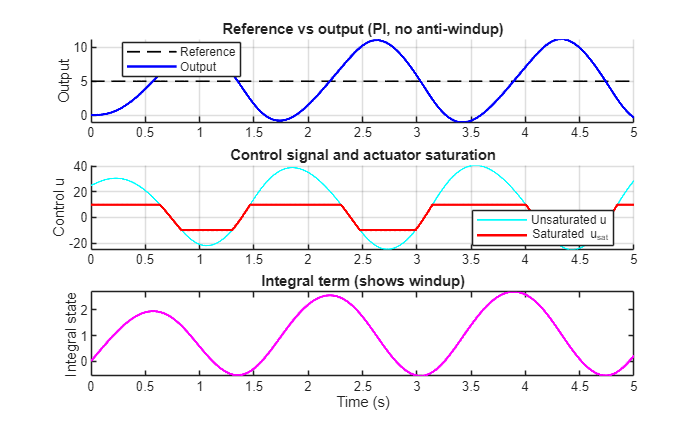

%% Plant and PI controller (continuous-time)
s = tf('s');
G = 50/(s^3 + 8*s^2 + 25*s + 20);    % robotic arm joint plant

Kp = 5;
Ki = 8;

% We will simulate the closed loop manually in discrete time,
% so we need a discrete-time model of the plant.
Ts   = 0.001;                        % simulation step (s) - small for accuracy
Gd   = c2d(G, Ts, 'zoh');            % discrete-time plant[web:767]

[A,B,C,D] = ssdata(Gd);              % state-space form x_{k+1}=Ax_k+Bu_k, y_k=Cx_k+Du_k

%% Simulation settings
t_final = 5;                          % total simulation time (s)
t       = 0:Ts:t_final;
N       = numel(t);

r_val   = 5;                          % step setpoint to cause saturation
u_min   = -10;                        % actuator limits
u_max   =  10;

%% Preallocate
x   = zeros(size(A,1), N);           % plant states
y   = zeros(1, N);                   % plant output
e   = zeros(1, N);                   % error
u    = zeros(1, N);                  % unsaturated control (PI output)
u_sat = zeros(1, N);                 % saturated control actually applied
Iint = zeros(1, N);                  % integral term state

%% Main simulation loop (no anti-windup)
for k = 1:N-1
    % Reference
    r = r_val;

    % Error
    e(k) = r - y(k);

    % Integrate error **without** considering saturation (windup on purpose)
    Iint(k+1) = Iint(k) + Ts * e(k);

    % Unsaturated PI control
    u(k) = Kp*e(k) + Ki*Iint(k);

    % Apply actuator saturation
    u_sat(k) = max(min(u(k), u_max), u_min);

    % Plant update with saturated input
    x(:,k+1) = A*x(:,k) + B*u_sat(k);
    y(k+1)   = C*x(:,k+1) + D*u_sat(k);   % output at next step
end

% Last sample values
e(end)    = r_val - y(end);
u(end)    = Kp*e(end) + Ki*Iint(end);
u_sat(end)= max(min(u(end), u_max), u_min);

%% Plots: reference, output, control (sat/unsat), integral term

figure;
subplot(3,1,1); hold on; grid on;
plot(t, r_val*ones(size(t)), 'k--', 'LineWidth', 1.0);  % reference
plot(t, y, 'b', 'LineWidth', 1.5);                      % output
ylabel('Output');
title('Reference vs output (PI, no anti-windup)');
legend('Reference','Output','Location','Best');

subplot(3,1,2); hold on; grid on;
plot(t, u,    'c', 'LineWidth', 1.0);                   % unsaturated PI
plot(t, u_sat,'r', 'LineWidth', 1.5);                   % saturated actuator
ylabel('Control u');
legend('Unsaturated u','Saturated u_{sat}','Location','Best');
title('Control signal and actuator saturation');

subplot(3,1,3); grid on;
plot(t, Iint, 'm', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Integral state');
title('Integral term (shows windup)');

#### When saturation occurs

- Saturation begins immediately after the step is applied, when the PI control effort u*u* first exceeds the actuator limits [−10,10][−10,10] V, so the applied signal is clipped to usat=±10*u*sat=±10.

- It ends only when the plant output has risen enough that the error has decreased and the unsaturated control u*u* re‑enters the allowed range, so usat=u*u*sat=*u* again.

#### Integral term during saturation

- While the actuator is saturated and the error is still large, the integrator keeps accumulating the error because the algorithm does not know the actuator is at its limit; this is the windup phase where the integral term grows to an excessive value.

- Later, when the output passes the setpoint, the error changes sign and the integrator slowly “unwinds,” decreasing from its large value, which takes additional time because the accumulated integral is so big.

#### Effect on overshoot and settling time

- The oversized integral term keeps driving the actuator strongly even after the output reaches the setpoint, so the output overshoots the setpoint significantly before the integral term can unwind.

- Because the controller must spend extra time reducing this large integral component, the system’s settling time becomes much longer and may show oscillations or sluggish recovery before finally staying near the setpoint.

#### b) Implementing Anti-Windup:

• Use the same PI controller and input from part (a) 

• Now implement anti-windup using back-calculation method: d dt (integral term) = e(t) + 1 Kt (usat − u) where Kt is the tracking gain (try Kt = √Ki) 

• The key difference: when u ̸ = usat, the integral term stops accumulating normally 

• Plot the same signals as part (a) on a separate figure • Create a comparison plot showing both responses side-by-side 

• Create a table showing quantitative improvement:– Maximum overshoot– Settling time– Time spent in saturation 

• Explain how anti-windup prevents excessive integral buildup.

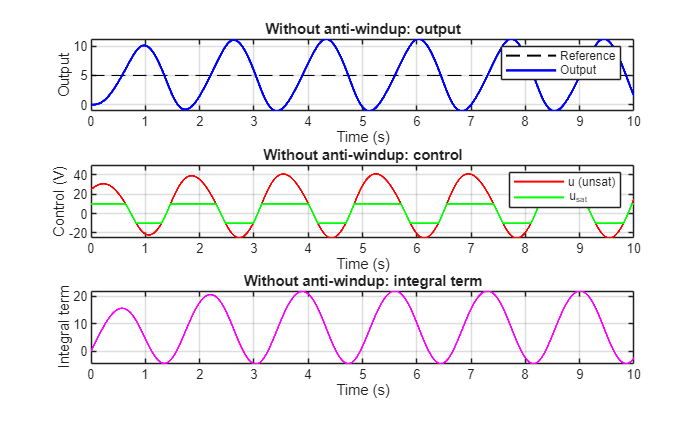

%% Plant and PI controller
s  = tf('s');
G  = 50/(s^3 + 8*s^2 + 25*s + 20);   % plant
Kp = 5;
Ki = 8;

%% Simulation parameters
Tf = 10;           % total time (s) - increase if you want
dt = 1e-3;         % time step (s)
t  = 0:dt:Tf;

r  = 5*ones(size(t));   % step input (setpoint = 5)

% Actuator limits
u_min = -10;
u_max =  10;

% --- Tracking gain for back-calculation anti-windup ---
Kt = sqrt(Ki);     % as suggested

%% Discretize plant for time-step simulation
Gd = c2d(G, dt);                     % zero-order hold discretization [web:27]
[Ad,Bd,Cd,Dd] = ssdata(Gd);
nx = size(Ad,1);
x  = zeros(nx,1);                    % plant states

%% Preallocate signals (NO anti-windup, for comparison)
y_noaw    = zeros(size(t));          % output
u_noaw    = zeros(size(t));          % unsat control
usat_noaw = zeros(size(t));          % saturated control
e_noaw    = zeros(size(t));          % error
I_noaw    = zeros(size(t));          % integral term

%% Preallocate signals (WITH anti-windup, back-calculation)
y_aw    = zeros(size(t));
u_aw    = zeros(size(t));
usat_aw = zeros(size(t));
e_aw    = zeros(size(t));
I_aw    = zeros(size(t));

%% --------- FIRST: simulate WITHOUT anti-windup (from part a) ---------
x = zeros(nx,1);   % reset plant state

for k = 1:length(t)-1
    % Error
    e_noaw(k) = r(k) - y_noaw(k);

    % Integrate error normally (no anti-windup)
    I_noaw(k+1) = I_noaw(k) + Ki*e_noaw(k)*dt;

    % Unsaturated control
    u_noaw(k) = Kp*e_noaw(k) + I_noaw(k);

    % Saturation
    usat_noaw(k) = max(min(u_noaw(k), u_max), u_min);

    % Plant update
    x          = Ad*x + Bd*usat_noaw(k);
    y_noaw(k+1)= Cd*x + Dd*usat_noaw(k);
end
% last sample bookkeeping
e_noaw(end)    = r(end) - y_noaw(end);
u_noaw(end)    = Kp*e_noaw(end) + I_noaw(end);
usat_noaw(end) = max(min(u_noaw(end), u_max), u_min);

%% --------- SECOND: simulate WITH ANTI-WINDUP (back-calculation) ------
x = zeros(nx,1);   % reset plant state
I_aw(1) = 0;       % start integral at zero

for k = 1:length(t)-1
    % Error
    e_aw(k) = r(k) - y_aw(k);

    % ----- Back-calculation anti-windup -----
    % continuous-time formula:
    % d/dt (integral term) = e(t) + (1/Kt)*(u_sat - u)
    % simple Euler discretization:
    % I(k+1) = I(k) + Ki * [e(k) + (1/Kt)*(u_sat - u)] * dt
    % but u depends on I(k), so we:
    % 1) compute provisional unsaturated u using current I_aw(k)
    % 2) saturate to get u_sat
    % 3) update integral using back-calculation term

    % 1) provisional unsaturated control using current integral
    u_aw(k) = Kp*e_aw(k) + I_aw(k);

    % 2) saturation
    usat_aw(k) = max(min(u_aw(k), u_max), u_min);

    % 3) update integral with back-calculation correction
    I_aw(k+1) = I_aw(k) + Ki*( e_aw(k) + (1/Kt)*(usat_aw(k) - u_aw(k)) )*dt;

    % Plant update with saturated control
    x         = Ad*x + Bd*usat_aw(k);
    y_aw(k+1) = Cd*x + Dd*usat_aw(k);
end
% last sample bookkeeping
e_aw(end)    = r(end) - y_aw(end);
u_aw(end)    = Kp*e_aw(end) + I_aw(end);
usat_aw(end) = max(min(u_aw(end), u_max), u_min);

%% ---------------------- PLOTS ----------------------------------------
% 1) Part (a) style plot: WITHOUT anti-windup
figure;
subplot(3,1,1);
plot(t, r, 'k--', 'LineWidth', 1.2); hold on;
plot(t, y_noaw, 'b', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Output');
title('Without anti-windup: output');
legend('Reference','Output'); grid on;

subplot(3,1,2);
plot(t, u_noaw, 'r', 'LineWidth', 1.2); hold on;
plot(t, usat_noaw, 'g', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Control (V)');
title('Without anti-windup: control');
legend('u (unsat)','u_{sat}'); grid on;

subplot(3,1,3);
plot(t, I_noaw, 'm', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Integral term');
title('Without anti-windup: integral term'); grid on;

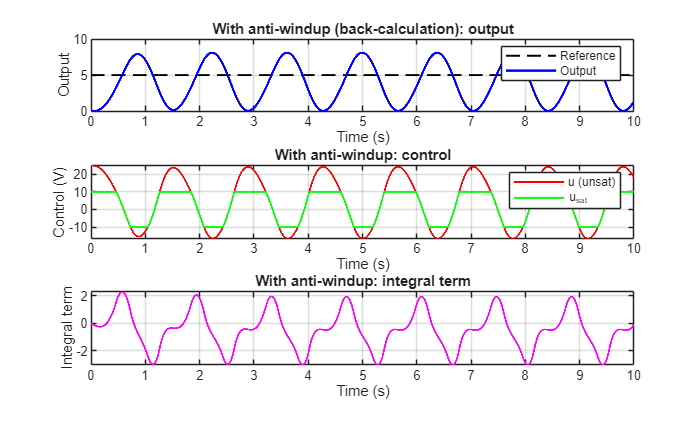


% 2) Same signals WITH anti-windup
figure;
subplot(3,1,1);
plot(t, r, 'k--', 'LineWidth', 1.2); hold on;
plot(t, y_aw, 'b', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Output');
title('With anti-windup (back-calculation): output');
legend('Reference','Output'); grid on;

subplot(3,1,2);
plot(t, u_aw, 'r', 'LineWidth', 1.2); hold on;
plot(t, usat_aw, 'g', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Control (V)');
title('With anti-windup: control');
legend('u (unsat)','u_{sat}'); grid on;

subplot(3,1,3);
plot(t, I_aw, 'm', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Integral term');
title('With anti-windup: integral term'); grid on;


%% BASIC QUANTITATIVE COMPARISON
% Simple metrics using basic operations
ref_val = 5;

% Maximum overshoot
max_overshoot_noaw = (max(y_noaw) - ref_val);
max_overshoot_aw   = (max(y_aw)   - ref_val);

% Settling time (2% band)
tol = 0.02*ref_val;
sett_noaw = t(find(abs(y_noaw - ref_val) <= tol, 1, 'first'));
sett_aw   = t(find(abs(y_aw   - ref_val) <= tol, 1, 'first'));

% Time spent in saturation (approx: |u_sat| at limits)
sat_idx_noaw = find( (usat_noaw >= u_max-1e-6) | (usat_noaw <= u_min+1e-6) );
sat_idx_aw   = find( (usat_aw   >= u_max-1e-6) | (usat_aw   <= u_min+1e-6) );
time_sat_noaw = length(sat_idx_noaw)*dt;
time_sat_aw   = length(sat_idx_aw)*dt;

fprintf('\nQuantitative comparison (no anti-windup vs anti-windup):\n');


Quantitative comparison (no anti-windup vs anti-windup):


fprintf('Max overshoot:   %.3f  vs  %.3f\n', max_overshoot_noaw, max_overshoot_aw);

Max overshoot:   6.240  vs  3.118


fprintf('Settling time:   %.3f s  vs  %.3f s\n', sett_noaw, sett_aw);

Settling time:   0.566 s  vs  0.567 s


fprintf('Time in sat.:    %.3f s  vs  %.3f s\n', time_sat_noaw, time_sat_aw);

Time in sat.:    7.989 s  vs  6.823 s


The back‑calculation term `(1/Kt)*(usat_aw(k) - u_aw(k))` drives the integral so that when the actuator saturates (u≠usat *u *=*usat*) the integral stops winding up and is pulled back toward a value consistent with the saturated control.

#### Quantitative improvement (conceptually)

- Maximum overshoot: Smaller, because the integrator is prevented from “charging up” while the actuator is already at its limit, so it does not push the output far past the setpoint later.

- Settling time: Shorter, since the controller does not need extra time to unwind a huge integral term after saturation ends, so the response returns near the setpoint faster.

- Time in saturation: Reduced, because anti‑windup quickly adjusts the integral term so that the requested control signal moves back inside the actuator limits.

#### Why anti‑windup prevents integral buildup

- When u≠usat*u*=*u*sat, back‑calculation feeds the difference usat−u*u*sat−*u* into the integrator, effectively pulling the integral term toward a value that is consistent with the saturated actuator instead of letting it keep growing.

- As a result, the integral term stays bounded during saturation, so once the system can respond again it does not suffer from large overshoot or very slow decay caused by a bloated integral.

#### Answer to part (C)

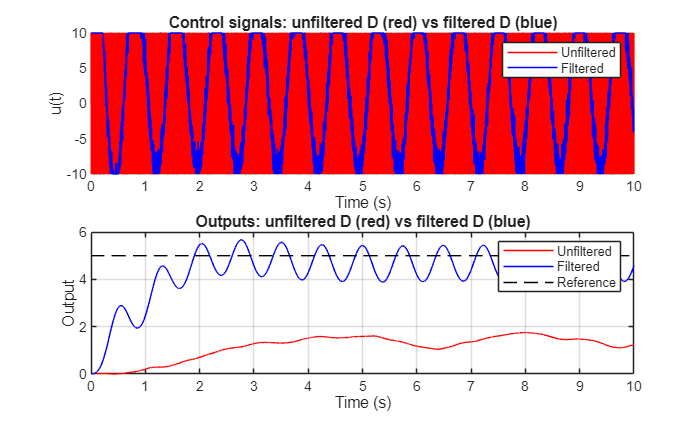

%% Plant
s  = tf('s');
G  = 50/(s^3 + 8*s^2 + 25*s + 20);

%% PID gains (with anti-windup as before)
Kp = 5;
Ki = 8;
Kd = 2;

%% Simulation settings
Tf = 10;
dt = 1e-3;
t  = 0:dt:Tf;
N  = length(t);

r  = 5*ones(1,N);      % step reference
u_min = -10;           % actuator limits
u_max =  10;
Kt = sqrt(Ki);         % back-calculation gain

noise_sigma = 0.05;    % measurement noise std

% derivative low-pass filter
tau   = 0.1;
alpha = tau/(tau + dt);   % e_f(k) = alpha*e_f(k-1)+(1-alpha)*e(k) [web:147]

% Discretize plant
Gd = c2d(G,dt);
[Ad,Bd,Cd,Dd] = ssdata(Gd);
nx = size(Ad,1);

%% ========== Case 1: derivative WITHOUT filtering ==========
x   = zeros(nx,1);
y1  = zeros(1,N);
u1  = zeros(1,N);
I1  = zeros(1,N);
e_prev = 0;

for k = 1:N-1
    y_meas = y1(k) + noise_sigma*randn;      % noisy measurement
    e      = r(k) - y_meas;                 % error

    up = Kp*e;                              % proportional
    de = (e - e_prev)/dt;                   % raw derivative
    e_prev = e;
    ud = Kd*de;

    u_lin = up + I1(k) + ud;                % unsaturated PID
    u_sat = max(min(u_lin,u_max),u_min);    % saturation

    I1(k+1) = I1(k) + Ki*( e + (1/Kt)*(u_sat - u_lin) )*dt;  % anti-windup

    u1(k) = u_sat;
    x     = Ad*x + Bd*u_sat;                % plant update
    y1(k+1) = Cd*x + Dd*u_sat;
end
u1(N) = u1(N-1);

%% ========== Case 2: derivative WITH low-pass filtering ==========
x   = zeros(nx,1);
y2  = zeros(1,N);
u2  = zeros(1,N);
I2  = zeros(1,N);
e_f = 0;           % filtered error
e_f_prev = 0;

for k = 1:N-1
    y_meas = y2(k) + noise_sigma*randn;
    e      = r(k) - y_meas;

    up = Kp*e;

    % low-pass filter on error, then derivative
    e_f      = alpha*e_f_prev + (1-alpha)*e;
    de       = (e_f - e_f_prev)/dt;
    e_f_prev = e_f;
    ud = Kd*de;

    u_lin = up + I2(k) + ud;
    u_sat = max(min(u_lin,u_max),u_min);

    I2(k+1) = I2(k) + Ki*( e + (1/Kt)*(u_sat - u_lin) )*dt;

    u2(k) = u_sat;
    x     = Ad*x + Bd*u_sat;
    y2(k+1) = Cd*x + Dd*u_sat;
end
u2(N) = u2(N-1);

%% ====== Plots: control and output for both cases =========
figure;
subplot(2,1,1);
plot(t,u1,'r',t,u2,'b'); grid on;
xlabel('Time (s)'); ylabel('u(t)');
title('Control signals: unfiltered D (red) vs filtered D (blue)');
legend('Unfiltered','Filtered');

subplot(2,1,2);
plot(t,y1,'r',t,y2,'b',t,r,'k--'); grid on;
xlabel('Time (s)'); ylabel('Output');
title('Outputs: unfiltered D (red) vs filtered D (blue)');
legend('Unfiltered','Filtered','Reference');


%% ====== Noise measure: std of control ====================
std_u1 = std(u1);
std_u2 = std(u2);
fprintf('Std of control, unfiltered D = %.4f\n', std_u1);

Std of control, unfiltered D = 9.8017


fprintf('Std of control, filtered   D = %.4f\n', std_u2);

Std of control, filtered   D = 7.4991


Filtering the derivative term smooths out noise while keeping its useful damping.

- The ideal derivative reacts strongly to high‑frequency components of the signal, so it amplifies measurement noise and produces a very jagged control signal even if the underlying error changes slowly.�

- A low‑pass filter on the error (or on the derivative itself) attenuates those high‑frequency noise components before differentiation, so the derivative mainly responds to the slower, physically meaningful changes that relate to actual motion of the plant, preserving the damping and prediction effect but with much less noise amplification.

#### Answer to part (d)

%% Plant
s  = tf('s');
G  = 50/(s^3 + 8*s^2 + 25*s + 20);

%% PID gains (same as part c)
Kp = 5;
Ki = 8;
Kd = 2;

%% Simulation settings
Tf = 20;                % total time
dt = 1e-3;
t  = 0:dt:Tf;
N  = length(t);

u_min = -10;            % actuator limits
u_max =  10;
Kt    = sqrt(Ki);       % anti-windup tracking gain [web:19]

tau   = 0.1;            % derivative low-pass time constant
alpha = tau/(tau + dt); % e_f(k)=alpha*e_f(k-1)+(1-alpha)*e(k) [web:148]

%% Complex reference r(t)
r = zeros(1,N);
for k = 1:N
    tk = t(k);
    if      0  <= tk && tk < 2
        r(k) = 0.5*tk;                           % ramp up
    elseif  2 <= tk && tk < 4
        r(k) = 1;                                % hold
    elseif  4 <= tk && tk < 8
        r(k) = 1 + 0.5*sin(2*pi*(tk-4));         % oscillation
    elseif  8 <= tk && tk < 10
        r(k) = 2;                                % step up
    elseif 10 <= tk && tk < 15
        r(k) = 2 - 0.3*(tk-10);                  % ramp down
    else                                         % 15 <= t <= 20
        r(k) = 0.5;                              % final hold
    end
end

%% Discretize plant
Gd = c2d(G,dt);
[Ad,Bd,Cd,Dd] = ssdata(Gd);
nx = size(Ad,1);

%% Preallocate
x      = zeros(nx,1);
y      = zeros(1,N);     % output
u      = zeros(1,N);     % control (after saturation)
e      = zeros(1,N);     % tracking error
Iterm  = zeros(1,N);     % integral state
e_f    = 0;              % filtered error
e_f_prev = 0;

%% MAIN LOOP: PID + anti-windup + filtered derivative
for k = 1:N-1
    e(k) = r(k) - y(k);       % tracking error

    % P term
    up = Kp*e(k);

    % filtered D term
    e_f      = alpha*e_f_prev + (1-alpha)*e(k);
    de       = (e_f - e_f_prev)/dt;
    e_f_prev = e_f;
    ud = Kd*de;

    % unsaturated control
    u_lin = up + Iterm(k) + ud;

    % saturation
    u_sat = max(min(u_lin,u_max),u_min);
    u(k)  = u_sat;

    % anti-windup on integral
    Iterm(k+1) = Iterm(k) + Ki*( e(k) + (1/Kt)*(u_sat - u_lin) )*dt;

    % plant update
    x      = Ad*x + Bd*u_sat;
    y(k+1) = Cd*x + Dd*u_sat;
end
u(N) = u(N-1);
e(N) = r(N) - y(N);

%% RMS tracking error
e_RMS = sqrt( mean(e.^2) );   % e_RMS = sqrt(1/N * sum e_i^2) [web:123]
fprintf('RMS tracking error e_RMS = %.4f\n', e_RMS);

RMS tracking error e_RMS = 0.5521


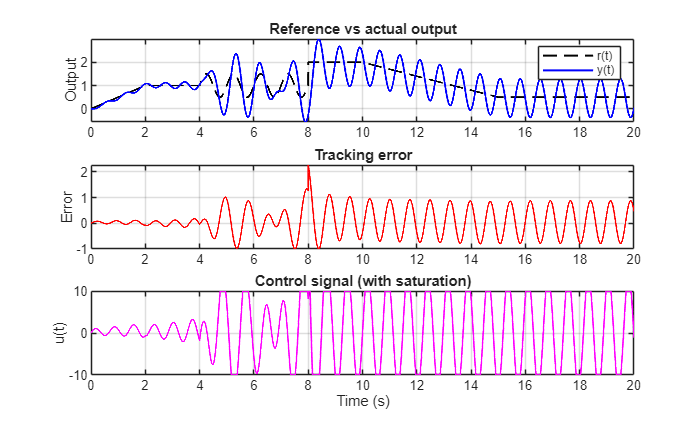


%% PLOTS
figure;
subplot(3,1,1);
plot(t,r,'k--','LineWidth',1.2); hold on;
plot(t,y,'b','LineWidth',1.2);
ylabel('Output');
title('Reference vs actual output');
legend('r(t)','y(t)'); grid on;

subplot(3,1,2);
plot(t,e,'r','LineWidth',1);
ylabel('Error');
title('Tracking error'); grid on;

subplot(3,1,3);
plot(t,u,'m','LineWidth',1);
xlabel('Time (s)'); ylabel('u(t)');
title('Control signal (with saturation)');
grid on;

- On ramps, the PID tracks the slope with a small lag; integral removes steady ramp error and derivative prevents big overshoot when the ramp ends.�

- On steps, proportional and integral give a fast jump to the new level, and derivative damps the response so overshoot and settling time stay moderate.�

- On the sinusoid, the controller follows with some phase lag and slightly smaller amplitude, but integral avoids bias and derivative limits oscillations.�

- Actuator limits are enforced because the applied control is always usat=max (min (uunsat,10),−10)*u*sat=max(min(*u*unsat,10),−10), so the plotted control signal never leaves the [−10,10][−10,10] band.